# **单块patch取向和patch大小**

**本脚本用于计算只有一块反应位点的颗粒的情况，这种情况下，可以人为的设置颗粒反应位点的朝向、覆盖范围以及朝向等参数。**

% filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\inclusion_1.mph';
% savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\202306011_savefile';
% theta_illum = 64;
% theta_span = 50;
% theta_dir = 0:20:180;
% I= zeros(201, 201, 36, length(theta_span));
% for ii = 1:length(theta_dir)
%     ii
%     p = mphrot(filename, 'theta_illum', theta_illum, 'theta_span', theta_span, 'theta_dir', theta_dir(ii), 'savepath', savepath);
%     p = p.mphcalcu();
%     p_36 = mphimage(p);
%     I(:, :, :, ii) = p_36.I;
% end
% save('D:\WJH\Ag_AgCl\Simulation\COMSOL\20230607_COMSOL_1patch_theta_list\Result.mat', 'I', 'p', '-v7.3');

# **两块patch取向和patch大小**

**本脚本用于计算同时有两个反应位点的颗粒的情况，这种情况下，可以人为的设置颗粒反应位点的朝向、覆盖范围以及朝向等参数。**

filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\COMSOL模型\inclusion_2.mph';
savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\20230624_两个反应位点先后反应';

% ------------------------- patch 角度矩阵 -----------------------------
M_Angles = zeros(70, 6);      % 角度矩阵，每一行对应一种状态，六列，从左到右依次是α、β、γ、theta_span、span1、span2
                            % 对称轴考虑7个取向，从正z轴指向正x轴
                            % 夹角考虑1种情况，180°
                            % 每个对称轴先后考虑两种情况，即一侧先生长，随后另一侧接着生长
M_Angles(:,1) = 0;
M_Angles(:,2) = 90;
M_Angles(:,4) = 180;
for ii = 1:7
    M_Angles((ii-1)*10+1:ii*10, 3) = (ii-1)*30-90;     % 从-90°到90°
    M_Angles((ii-1)*10+1:(ii-1)*10+5, 5) = 10:10:50;
    M_Angles((ii-1)*10+1:(ii-1)*10+5, 6) = 0;
    M_Angles((ii-1)*10+6:ii*10, 5) = 50;
    M_Angles((ii-1)*10+6:ii*10, 6) = 10:10:50;
end

theta_illum = 64;
I= zeros(201, 201, 36, length(M_Angles));
for ii = 21:length(M_Angles)
    ii
    p = mphrot(filename, 'theta_illum', theta_illum, 'savepath', savepath, ...
        'alpha', M_Angles(ii,1), ...
        'beta', M_Angles(ii,2), ...
        'gamma', M_Angles(ii,3), ...
        'included_angle', M_Angles(ii,4), ...

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2194.351831 秒。


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2271.082470 秒。


        'theta_span1', M_Angles(ii,5), ...

        'theta_span2', M_Angles(ii,6));
    p = p.mphcalcu();
    p_36 = mphimage(p);
    I(:, :, :, ii) = p_36.I;
    figure
    imagesc(sum(p_36.I, 3)); axis equal; axis off
end
save('D:\WJH\Ag_AgCl\Simulation\COMSOL\20230607_COMSOL_1patch_theta_list\Result.mat', 'I', 'p', '-v7.3');

# **两块patch取向不同**

**本脚本用于计算反应到后期，只剩下部分银孤岛情况下的散射图案。钱晨师兄认为如果金属的散射更强烈，那么图案应该会受到金属分布的调控：**

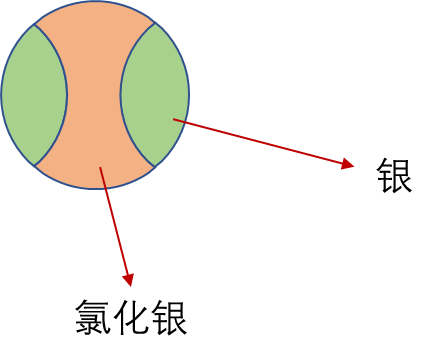

**本脚本只考虑了两个相同体积的斑块，其中两个斑块与球心所在平面域界面平行，两个斑块中心夹角从 0°(两斑块重合)增加到 180°(两斑块中心与球心共线)，夹角步长是 30°。**

ii = 7

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2675.655502 秒。


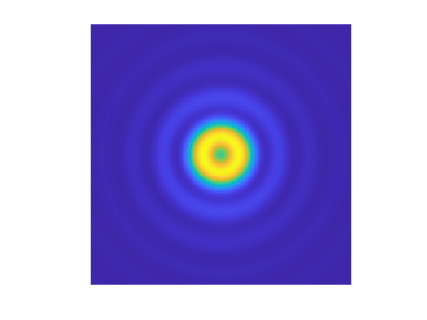

ii = 8

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2561.330092 秒。


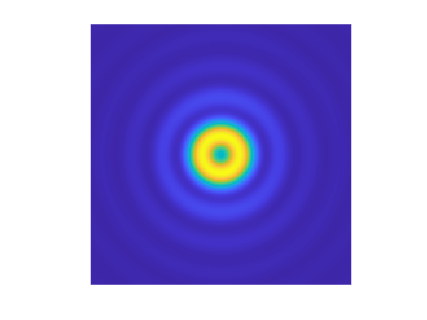

ii = 9

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2884.442015 秒。


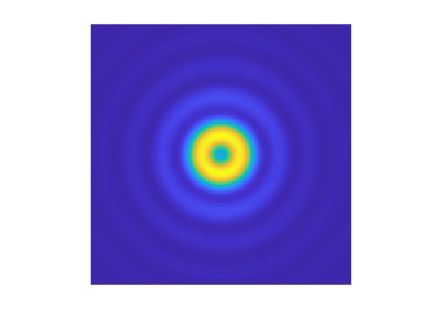

ii = 10

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 3049.402586 秒。


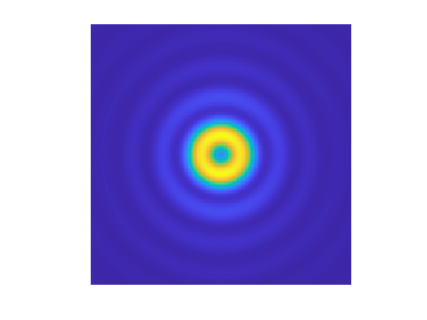

ii = 11

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2494.129345 秒。


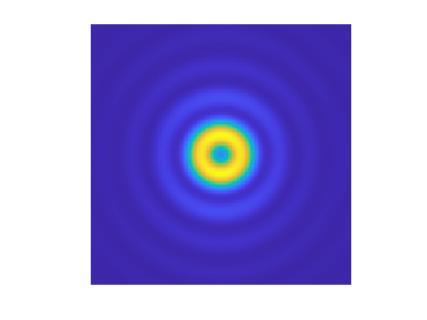

ii = 12

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2375.009000 秒。


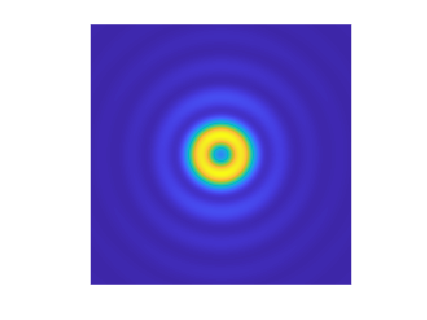

ii = 13

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2434.197701 秒。


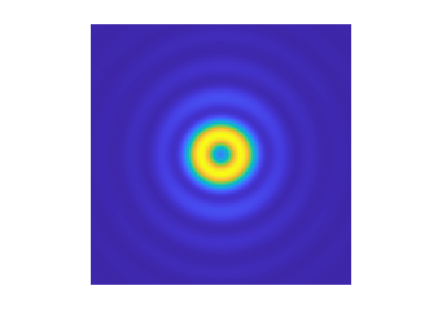

ii = 14

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 3185.794536 秒。


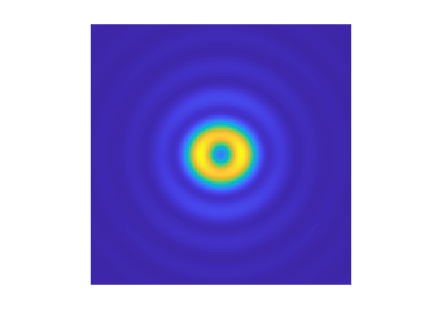

ii = 15

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2865.436222 秒。


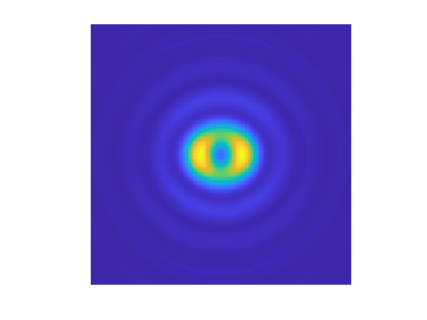

filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\COMSOL模型\inclusion_2_主体是氯化银-银斑块散布.mph';
savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\20230627-两个银斑块不同朝向';

% ------------------------- patch 角度矩阵 -----------------------------
M_Angles = zeros(7, 6);      % 角度矩阵，每一行对应一种状态，六列，从左到右依次是α、β、γ、included_angle、span1、span2

M_Angles(:,1) = 90;
M_Angles(:,2) = 90;
M_Angles(:,3) = 0;
M_Angles(:,4) = (0:30:180)';
M_Angles(:,5) = 50;
M_Angles(:,6) = 50;

theta_illum = 64;

I= zeros(201, 201, 36, length(M_Angles));

for ii = 1:length(M_Angles)
    ii
    p = mphrot(filename, 'theta_illum', theta_illum, 'savepath', savepath, ...
        'alpha', M_Angles(ii,1), ...
        'beta', M_Angles(ii,2), ...
        'gamma', M_Angles(ii,3), ...
        'included_angle', M_Angles(ii,4), ...
        'theta_span1', M_Angles(ii,5), ...
        'theta_span2', M_Angles(ii,6));
    p = p.mphcalcu();
    p_36 = mphimage(p);
    I(:, :, :, ii) = p_36.I;
    figure
    imagesc(sum(p_36.I, 3)); axis equal; axis off
end
save(fullfile(savepath,'Result.mat'), 'I', '-v7.3');

# **核壳结构**

**本脚本考虑反应情况，即从 AgNp 按照壳层内收缩的反应方式进行反应的情况下，不同反应进程所对应的图案/强度变化。**

ii = 1

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2682.953441 秒。


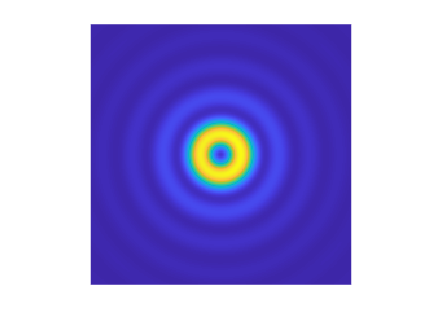

ii = 2

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2664.701162 秒。


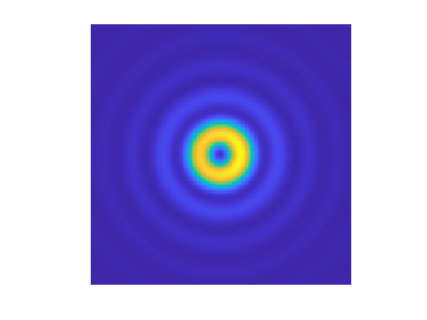

ii = 3

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2702.787886 秒。


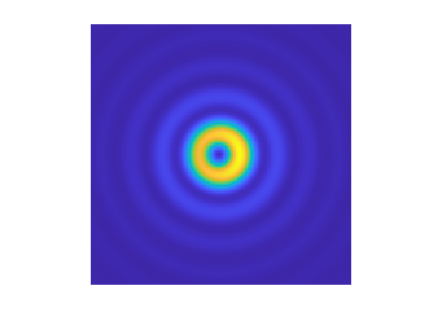

ii = 4

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 2641.494115 秒。


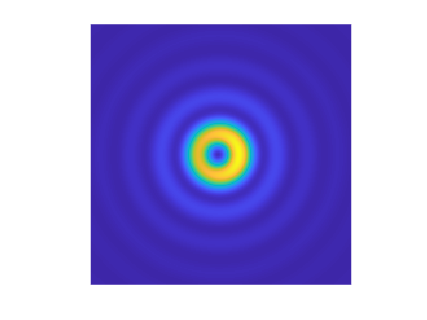

ii = 5

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 7042.956453 秒。


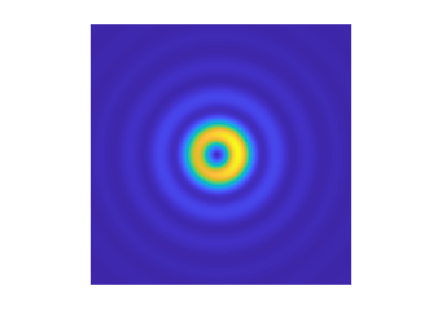

ii = 6

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


历时 4151.740507 秒。


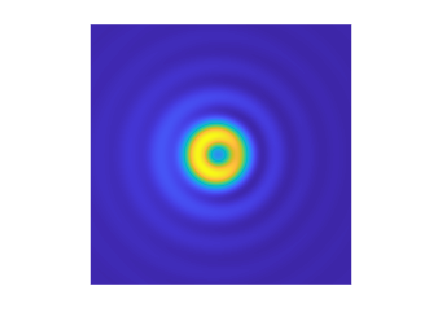

% filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\core_shell.mph';
% savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\202306011_core_shell';

% theta_illum = 64;

% r_Ag = 1:28;
% I= zeros(201, 201, 36, length(r_Ag));
% for ii = 1:length(r_Ag)
%     ii
%     p = mphrot(filename, 'theta_illum', theta_illum, 'r_Ag', r_Ag(ii), 'savepath', savepath);
%     p = p.mphcalcu();
%     p_36 = mphimage(p);
%     I(:, :, :, ii) = p_36.I;
% end
% save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');
% 

# **单个球形颗粒情况**

**本脚本专门计算单球形颗粒的散射情况，只能考虑 AgCl 球和 Ag 球。**

filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\COMSOL模型\single_particle.mph';
savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\20230627_single_particle_Ag-AgCl';
theta_illum = 64;
mats = {'Ag', 'AgCl'};
I= zeros(201, 201, 36, length(mats));
for ii = 1:length(mats)
    p = mphrot(filename, 'theta_illum', theta_illum, 'mat', mats{ii}, 'savepath', savepath);
    p = p.mphcalcu();
    p_36 = mphimage(p);
    I = p_36.I;
end
save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');

# **自由空间中核壳结构**

**本脚本是为了看核壳结构在自由空间中的散射是什么情况。之前用核壳结构的Mie理论给出的结果很离谱，后面证实了code有问题，但暂时没有查出来问题出在哪里，所以先用COMSOL验证一下。**

**本脚本考虑一个总半径为 30nm 的 AgCl 包 Ag 的核壳结构，但没有考虑不同占比的 AgCl 引起的体积膨胀效应。**

% filename = 'E:\work\SPR-DF\模拟\COMSOL\COMSOL模型\core_shell_free_space.mph';
% savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\20230616_自由空间中核壳结构散射';
% theta_illum = 0;
% r_Ag = 1:28;
% num = 1;        % 只算单个角度，即垂直入射，因为颗粒具有旋转对称性，所以什么角度结果都是一样的
% I= zeros(201, 201, num, length(r_Ag));
% for ii = 1:length(r_Ag)
%     ii
%     p = mphrot(filename, 'theta_illum', theta_illum, 'r_Ag', r_Ag(ii), 'savepath', savepath, 'num', num);
%     p = p.mphcalcu();
%     p_36 = mphimage(p);
%     I(:, :, :, ii) = p_36.I;
% end
% save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');

# **单个纳米棒情况**

**本脚本专门计算单个椭球颗粒的情况。可以修改的参数有椭球的长径比（AR）、椭球直径以及椭球距离基底的高度等，具体可以查看相应的COMSOL模型。**

% filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\COMSOL模型\nanorod.mph';
% savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\202230620_nanorod';
% theta_illum = 64;
% AR = 1.21:0.2:4.01;
% I= zeros(201, 201, 36, length(AR));
% for ii = 7:length(AR)
%     ii
%     p = mphrot(filename, 'theta_illum', theta_illum, 'savepath', savepath, 'AR', AR(ii), 'd_rod', 60 ,'num', 36);
%     p = p.mphcalcu();
%     p_36 = mphimage(p);
%     I(:, :, :, ii) = p_36.I;
%     figure
%     imagesc(sum(p_36.I, 3)); axis equal; axis off
% end
% save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');

# **基于双曲线方法生成单个反应位点**

filename = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\COMSOL模型\inclusion_1_hyp.mph';
savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\20230626_COMSOL_1patch_hyper';
theta_illum = 64;
a = (50:-8:10) - 30;
theta_dir = 90;
I= zeros(201, 201, 36, length(a));
for ii = 1:length(a)
    ii
    p = mphrot(filename, 'theta_illum', theta_illum, ...
        'a', a(ii),'theta_dir', theta_dir, 'savepath', savepath);
    p = p.mphcalcu();
    p_36 = mphimage(p);
    I(:, :, :, ii) = p_36.I;
    figure
    imagesc(sum(p_36.I, 3)); axis equal; axis off
end
save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');